# Edge Extraction

Goal: extract the edges of an image 

https://www.mathworks.com/help/images/object-analysis.html#f11-12512

Methods tested: Canny detector ; boundary extraction ; Hough line transform

clear all;
close all;

## 0) Import the data

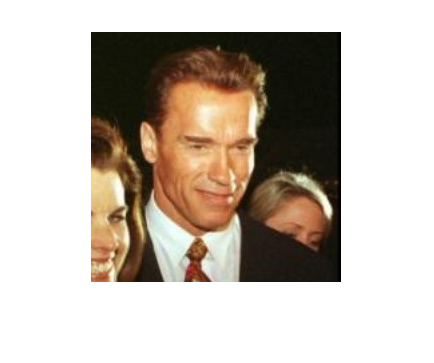

% import the data
im = im2double(imread('lfw/Arnold_Schwarzenegger_0004.jpg'));
imshow(im)

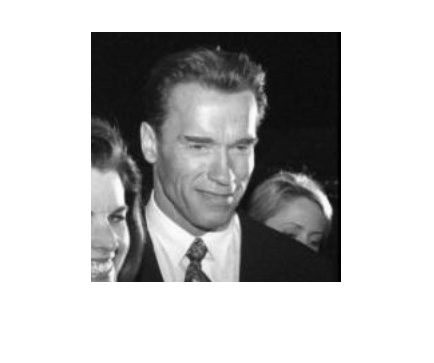

% grayscale version
im_g = rgb2gray(im);
imshow(im_g)

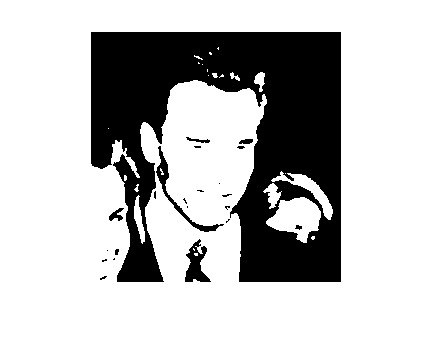


% BW version: from locally adaptive Otsu's thresholding
im_bw = imbinarize(im_g);
imshow(im_bw)

## Canny edge detector

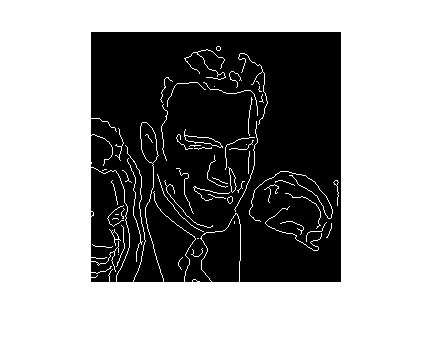

% hyperparameters
thresh = 0.2; % threshold for edge detection
k = 2; % size of dilatation structuring element

% edge extraction
edges =  edge3(im_g, 'approxcanny', thresh);
imshow(edges)

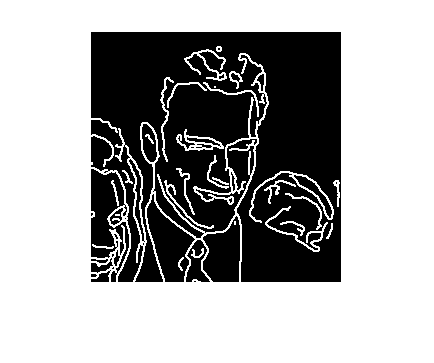


% edge dilatation
SE = ones(k,k);
edges_d = imdilate(edges, SE);
imshow(edges_d)

## Unsuccessful experiments

Boundaries extraction

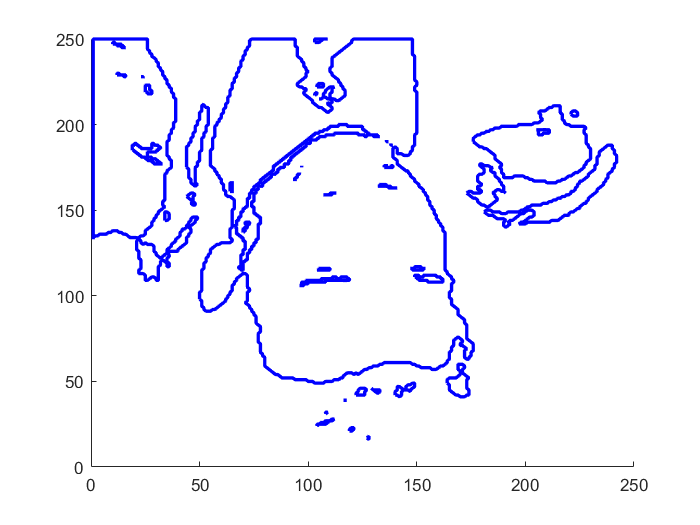

B = bwboundaries(im_bw);
 
figure 
hold on
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'b', 'LineWidth', 2)
end

function edges = canny_extractor(im, thresh, show)
    % uncanny edge detector    
    BW = edge3(im,'approxcanny',thresh);
    
    % check if we have a grayscale or an rgb input image
    if size(im,3) == 1
        edges = BW;
    else
        edges = 1/3*(BW(:,:,1) + BW(:,:,2) + BW(:,:,3)); 
        
        if show
            subplot(1,3,1)
            imshow(BW(:,:,1))
            subplot(1,3,2)
            imshow(BW(:,:,2))
            subplot(1,3,3)
            imshow(BW(:,:,3))
            figure
        end
    end
end

function lines = hough_extractor(im_bw)
    % hyperparameters
    d_rho = 1;
    thetas = -90:0.1:89.5;
    min_length = 1;
    fill_gap = 5;
    peakNum = 30;

    % compute Hough transform
    [H, theta, rho] = hough(im_bw, 'RhoResolution', d_rho, 'Theta', thetas);
    
    % detect peaks in Hough transform
    P = houghpeaks(H, peakNum, 'threshold', ceil(0.2*max(H(:)))); % detect peaks
    lines = houghlines(im_bw, theta, rho, P, 'FillGap', fill_gap, 'MinLength', min_length); % extract lines from peaks
    
    % convert struct to array
    xy_begin = reshape([lines.point1], 2, []).';
    xy_end = reshape([lines.point2], 2, []).';
    %lines = [xy_begin, xy_end];
    
    imshow(im_bw)
    hold on
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];
       plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
       % Plot beginnings and ends of lines
       plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
       plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
    end
end